
clc
close all
clear all

imaqhwinfo info = imaqhwinfo('winvideo',1) celldisp(info.SupportedFormats) vid = videoinput('winvideo',1,'YUY2_640x480'); set(vid,'ReturnedColorSpace','rgb'); preview(vid); pause input = getsnapshot(vid); figure('name','Input Image'); imshow(input); closepreview

## Get the Input Image

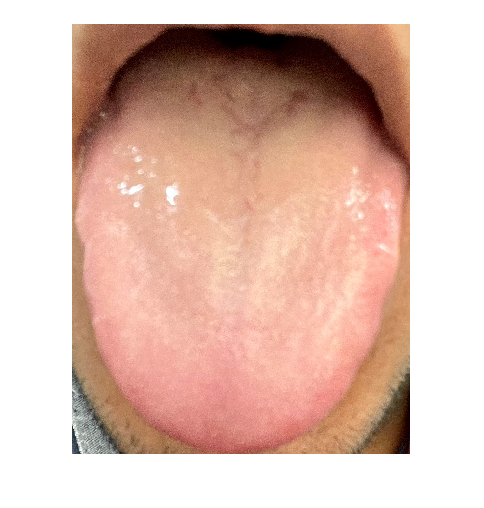

[file path] = imgetfile;
if file == 0
    warndlg('Please select input file');
else
    input = imread(file);
    figure('name','Input Image');
    imshow(input);
end

## color Conversion

RGB = (input);
R = RGB(:,:,1);
G = RGB(:,:,2);
B = RGB(:,:,3);

## Conversion Formula

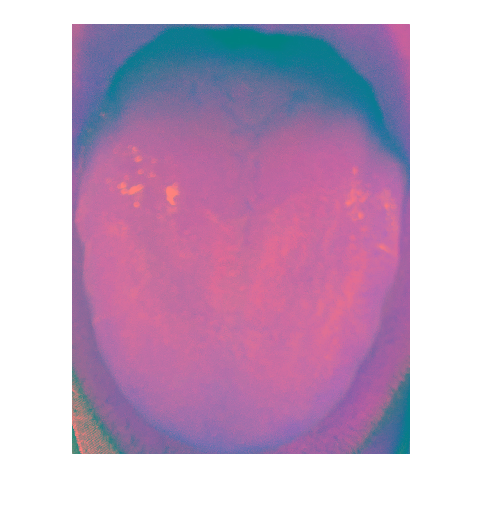

Y = 0.299   * R + 0.587   * G + 0.114 * B;
U = 128 - 0.168736 * R - 0.331264 * G + 0.5 * B;
V = 128 + 0.5 * R - 0.418688 * G - 0.081312 * B;
YUV=cat(3,Y,U,V);
figure('name','YUV Color Coversion');
imshow(YUV);

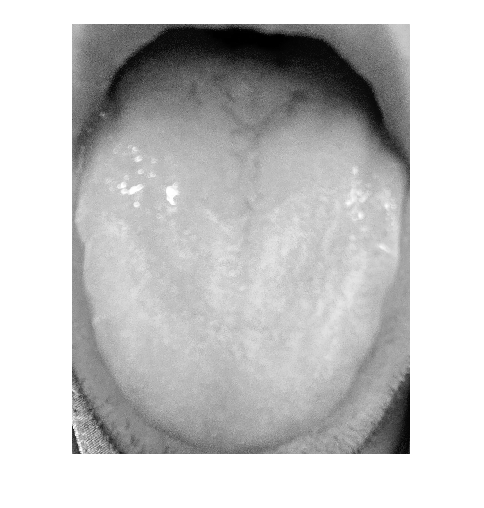


y_img = YUV(:,:,1);
figure('name','Luminance Image');
imshow(y_img,[]);

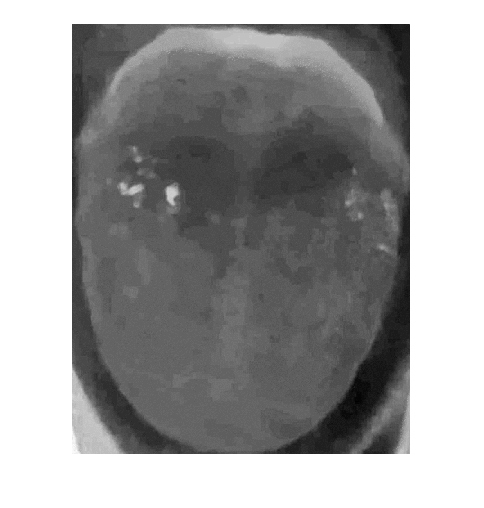

u_img = YUV(:,:,2);
figure('name','chrominance of U Image');
imshow(u_img,[]);

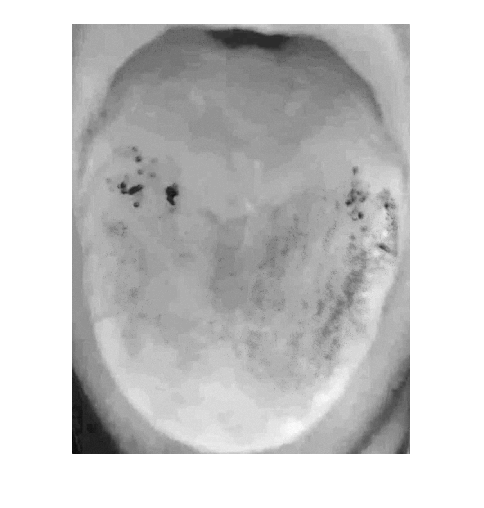

v_img = YUV(:,:,3);
figure('name','chrominance of V Image');
imshow(v_img,[]);

## Enhancment

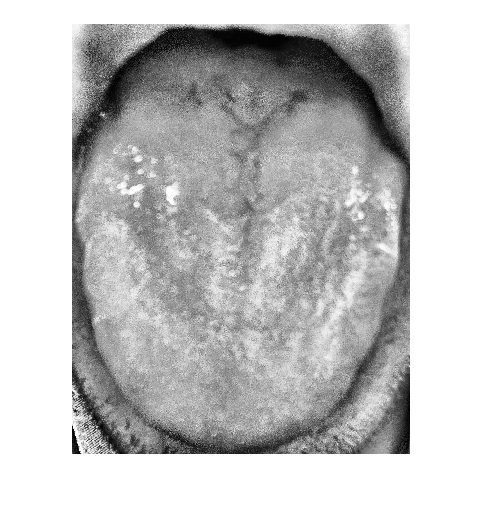

y_int = adapthisteq(y_img);
figure('name','Enhanced Intensity Image');
imshow(y_int,[]);

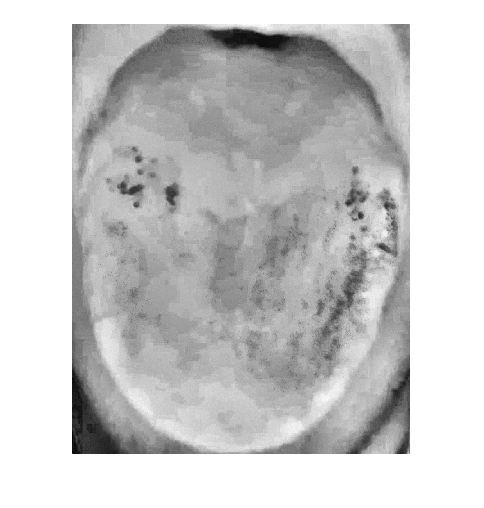


v_int = adapthisteq(v_img);
figure('name','Enhanced Image')
imshow(v_int,[]);



Y = single(y_int(:,:,1));
U = single(u_img(:,:,1));
V = single(v_int(:,:,1));

C = Y - 16;
D = U - 128;
E = V - 128;

## seprate RGb

R = uint8((298 * C + 409 * E + 128) / 256);
G = uint8((298 * C - 100 * D - 208 * E + 128) / 256);
B = uint8((298 * C + 516 * D + 128) / 256);

## Return Color RGB

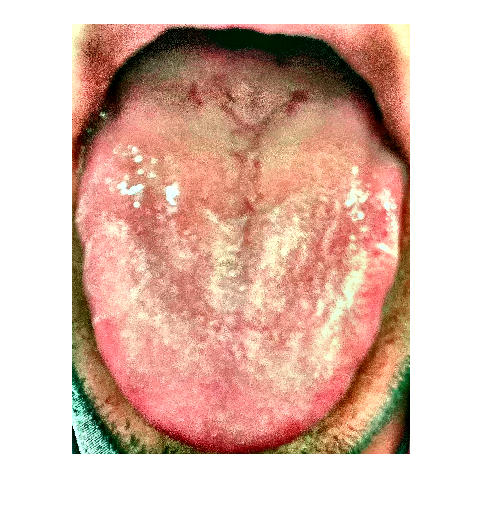

color_rgb(:,:,1) = R;
color_rgb(:,:,2) = G;
color_rgb(:,:,3) = B;

figure('name','Enhaced Color Image');
imshow(color_rgb,[]);

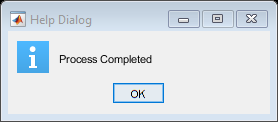

helpdlg('Process Completed');